# EXTRACT - newcomer example

This tutorial provides example code to get a newcomer started with EXTRACT.

Written by Fatih Dinc, 03/02/2021

## Run setup for initialization of path

extract_root_directory = setup;

## Load data

This example file contains a movie M, ground truth cell maps (S_ground) and traces (T_ground)

load(fullfile(extract_root_directory,'sample_data','example.mat'));

## Initialize configuration parameters

### **Essential parameters**

Without these essential parameters, EXTRACT will give an error:

config = get_defaults([]); %calls the defaults
config.avg_cell_radius=7; %Average cell radius is 7.

### **Optional but advised parameters**

Optional parameters but strongly advised to handpick:

%Movie is small enough that EXTRACT will not automatically partition this,
%but still a good idea to keep these in sight!
config.trace_output_option='raw'; % Choose 'nonneg' for non-negative Ca2+ traces, 'raw' for raw ones!
config.num_partitions_x=1;
config.num_partitions_y=1; 
%config.cellfind_filter_type='none'; % The movie is clean enough, no need for lowpass filtering
config.verbose=2; %Keeping verbose=2 gives insight into the EXTRACTion process, always advised to keep 2
config.spatial_highpass_cutoff=inf; % no need for highpass filtering
config.cellfind_filter_type ='none';
% Optionals whose defaults exist:
config.use_gpu=0; % This is a small dataset, will be fast on cpu anyways.
config.max_iter = 10; % 10 is a good number for this dataset
config.adaptive_kappa = 2;% Adaptive kappa is on for this movie. For an actual movie, keeping it off
config.cellfind_adaptive_kappa = 1;% Adaptive kappa is on for this movie. For an actual movie, keeping it off

% may be beneficial depending on the noise levels.
config.cellfind_min_snr=0.5;% Default snr is 1, lower this (never less than 0) to increase cell count at the expense of more spurious cells!
config.thresholds.T_min_snr=7;

config.visualize_cellfinding=1;

## Run EXTRACT

Perform the actual extraction

08-Nov-2023 20:28:59: Signal extraction will run on 1 partitions serially... 
08-Nov-2023 20:28:59: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.0 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 Using cell finding visualization tool...
	 	 	 	 noise std: 0.0203 
	 	 	 	 minimum magnitude: 0.0178 
	 	 	 20 cells found after a total of 21 steps... 
	 	 	 Updating S and T with alternating estimation...
	 	 	 End of iter # 1: # cells: 20 (0 removed) 
	 	 	 End of iter # 2: # cells: 20 (0 removed) 
	 	 	 End of iter # 3: # cells: 20 (0 removed) 
	 	 	 End of iter # 4: # cells: 20 (0 removed) 
	 	 	 End of iter # 5: # cells: 20 (0 removed) 
	 	 	 End of iter # 6: # cells: 20 (0 removed) 
	 	 	 End of iter # 7: # cells: 20 (0 removed) 
	 	 	 End of iter # 8: # cells: 20 (0 removed) 
	 	 	 End of iter # 9: # cells: 20 (0 removed) 
	 	 	 End of iter # 10: # cells: 20 (0 removed) 


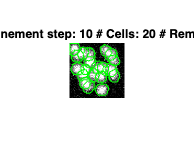

	 	 	 Providing raw traces... 
	 	 	 Count: 20 cells.
08-Nov-2023 20:29:31: Total of 20 cells are found.
08-Nov-2023 20:29:31: Removing duplicate cells...
08-Nov-2023 20:29:31: 20 cells were retained after removing duplicates.
08-Nov-2023 20:29:31: All done with EXTRACT! 


% Perform EXTRACTion:
output=extractor(M,config);

## Evaluate performance

Examine relative to ground truth

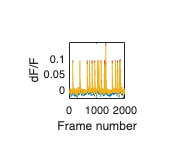

%% Matching ground truth to EXTRACTed signals
[h,w,k]=size(full(output.spatial_weights));
S_ex=reshape(full(output.spatial_weights),h*w,k);
idx_match = match_sets(S_ex, S_ground); %this is a very useful helper function, use this as you need!
% 
T_ex = output.temporal_weights';
% Perform multivariate linear regression for comparison
M_res=reshape(M,2500,2000);
X=mean(M_res,2);
M_res=(M_res-X)./X; %perform dfof
S=S_ex;
T_est=(S'*S)^(-1)*S'*M_res;
% Since this movie does not contain unfound cells or neuropils, this will
% be close to ground truth and EXTRACT outputs!
%%
pick=20;
plot(T_ex(idx_match(1,pick),:));
hold on
plot(T_ground(idx_match(2,pick),:))
hold on
plot(T_est(idx_match(1,pick),:))
ylabel('dF/F');
xlabel('Frame number')